# Atividade 04_02

Otávio Baziewicz Filho - 1942808

## Clear Workspace

clear all;
close all;
clc;

## Script

%Sigmoid
%Aloca uint8
%para depois usar funcao intlut (y1 é a LUT)
%Equação da sigmoide
slope = 0.74

slope = 0.7400

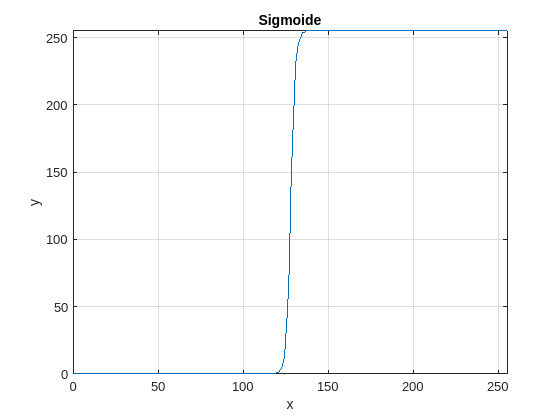

inflec = 127;
x = 0:1:255;
y1 = 1./(1 + exp(-slope*(x - inflec)));
y1n = mat2gray(y1);
y1n = uint8(y1n.*255);
%Display
figure, plot(y1n)
xlim([0 255]), ylim([0 255])
grid on
title('Sigmoide')
xlabel('x'), ylabel('y')

## **Sigmoide**

Aplique a função sigmoide para contrast streching especificada anteriormente (código exemplo) na imagem vpfig.png. Use a função intlut do MATLAB. Teste e mostre os resultados com diferentes valores para a variável ‘slope’, que determina a inclinação da sigmoide (‘slope’ maior: sigmoide mais ‘ingreme’).

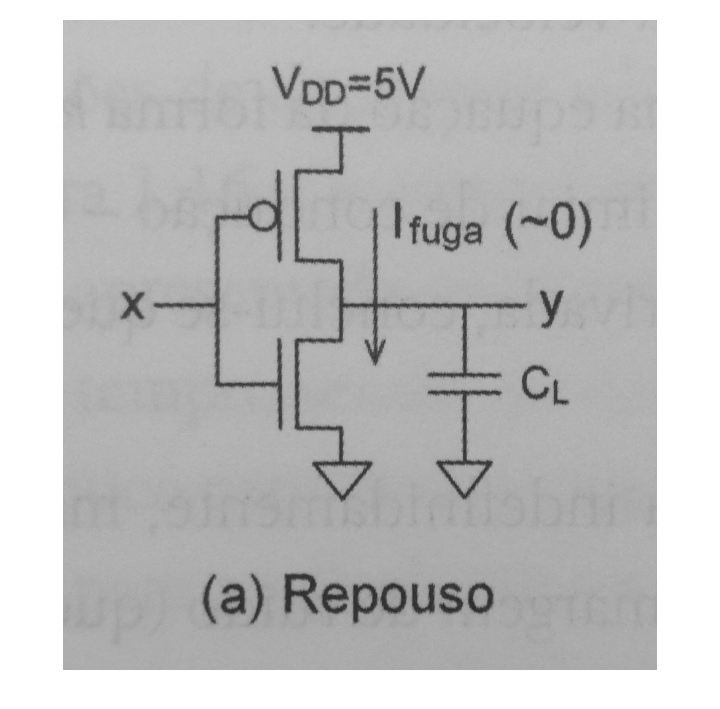

sourceImage = imread("vpfig.png");

processedImage = intlut(sourceImage, y1n);

figure, imshow(sourceImage)

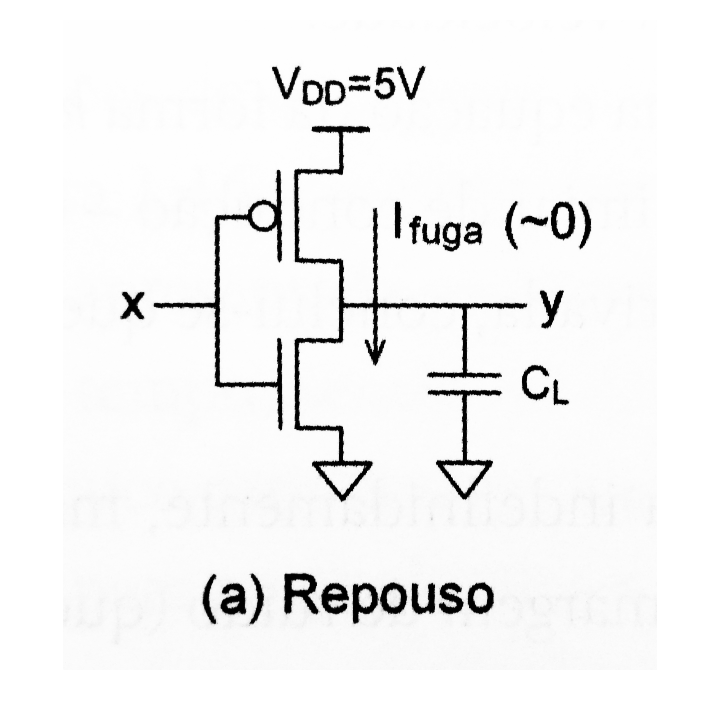

figure, imshow(processedImage);